Homework #10

## 1

Training datapoint:

X=[-1; 2]; y=2;

Initial weights:

w2=[ -0.2, -0.4;
0.4, -0.4;
0.1, 0.1];
b2=[ -0.5;
0.2;
0.1];
w3=[ 0.1, 0.1, 0.1];
b3=[ -0.1];

All nodes are sigmoid. Sigmoid activation function:

sigmoid = @(zl) 1.0 ./ (1.0+exp(-zl));

Cost function:

cost = @(y, al) 0.5* ((y-al).^2);

1a)

[1a pic]

z2 = w2*X + b2;
a2 = sigmoid(z2)

a2 =     0.2497
    0.2689
    0.5498


z3 = w3*a2 + b3;
a3 = sigmoid(z3)

a3 = 0.5017


datapoint_cost = cost(y, a3)

datapoint_cost = 1.1224

1b)


$$$\delta^L=\frac{\partial C}{\partial z^L}=\frac{\partial C}{\partial a^L} \frac{\partial a^L}{\partial z^L}$$$


And $$\frac{\partial C}{\partial a^L}=\frac{d}{da^L}[\frac{1}{2}(y-a^L)^2]=a^L-y=\nabla_{a^L}C$$

And $$\frac{\partial a^L}{\partial z^L}=\frac{d}{dz^L}(1+e^{-z^{L}})^{-1}=e^{-z^L}(1+e^{-z^L})^{-2}=\sigma '(z^L)$$

So $$\delta^L=\nabla_{a^L}C\odot\sigma '(z^L)=(a^L - y) \cdot e^{-z^L}(1+e^{-z^L})^{-2}$$

From the last layer's delta, we can find all other subsequent earlier layer delta using:


$$$\delta^l=(w^{l+1})^T\delta^{l+1}\odot\sigma '(z^l)$$$


And then for any layer, we can calculate its gradient and how much to adjust its weights based on its delta using:


$$$\nabla_{W^l}C=\delta^l(a^{l-1})^T$$$


1c)

[1c pic]

1d)

sigma_prime function:

sigma_prime = @(zl) exp(-zl)./ ((1+exp(-zl)).^2);

delta L calculation function:

calc_delta = @(y, al, zl) (al-y)*sigma_prime(zl);

Calculate gradient with respect to all weights

delta3 = calc_delta(y, a3, z3);
gradient_w3 = delta3*a2.'

gradient_w3 =    -0.0935   -0.1007   -0.2059


gradient_b3 = delta3

gradient_b3 = -0.3746


delta2 = (w3.' * delta3) .* sigma_prime(z2);
gradient_w2 = delta2*X.'

gradient_w2 =     0.0070   -0.0140
    0.0074   -0.0147
    0.0093   -0.0185


gradient_b2 = delta2

gradient_b2 =    -0.0070
   -0.0074
   -0.0093


1e) Direct perturbation approach for w2_12

epsilon = 0.002;

epsilon_w2 = w2;
epsilon_w2(1,2) = epsilon_w2(1,2) + epsilon;

epsilon_z2 = epsilon_w2*X + b2;
epsilon_a2 = sigmoid(epsilon_z2);
epsilon_z3 = w3*epsilon_a2 + b3;
epsilon_a3 = sigmoid(epsilon_z3);

epsilon_datapoint_cost = cost(y, epsilon_a3);

disp('direct perturbation approach:')

direct perturbation approach:


epsilon_delta = (epsilon_datapoint_cost - datapoint_cost) ./epsilon

epsilon_delta = -0.0141

which is pretty similar to our gradient calculated value:

disp('gradient calculation approach:')

gradient calculation approach:


disp(gradient_w2(1,2))

   -0.0140



1f)

eta = 1;

1 iteration of steepest-descent

new_w2 = w2 - (eta.*gradient_w2);
new_b2 = b2 - (eta.*gradient_b2);
new_w3 = w3 - (eta.*gradient_w3);
new_b3 = b3 - (eta.*gradient_b3);

new_z2 = new_w2*X + new_b2;
new_a2 = sigmoid(new_z2);
new_z3 = new_w3*new_a2 + new_b3;
new_a3 = sigmoid(new_z3)

new_a3 = 0.6347


disp('new datapoint cost:')

new datapoint cost:


new_datapoint_cost = cost(y, new_a3)

new_datapoint_cost = 0.9320

disp('old datapoint cost:')

old datapoint cost:


datapoint_cost

datapoint_cost = 1.1224

Yes.

[discuss]

## 2

X=[3,6,1,0,5,5,4,4,3,4,6,3,2,5,4,8,6,8, 9,8,3,6, 1,4,7,2,9,1,4,2,9,1,5;
9,1,5,7,5,5,2,2,2,0,2,4,1,2,9,8,8,10,1,3,4,6,10,7,2,7,4,9,4,6,8,9,4];
y=[2,3,1,1,3,3,3,3,1,3,3,1,1,3,2,2,2, 2,3,3,1,2, 1,2,3,1,2,1,1,1,2,1,3];

Input space:

x1=[0:0.1:10];
x2=[0:0.1:10];

2a) Classification:

adapted from "neural_networks3_simple_2d_classification.m"

% for classification, need to turn labels into matrix format:
T=zeros(max(y),length(y)); for i=1:length(y); T(y(i),i)=1; end

% Create network: specify number of neurons in each layer:
rng(3456);
clear net1
% [e.g., [2 6 2] would create 3 hidden layers with 2,6,2 neurons in each]
net1 = patternnet([3 3]); % 2 hidden layers with 3 neurons each. sure.
disp('net1 = patternnet([3 3]);');

net1 = patternnet([3 3]);



% don't divide data into training, testing, validation.
net1.divideFcn='';

% Train network:
net1 = train(net1,X,T);
disp('net1 = train(net1,X,T);');

net1 = train(net1,X,T);


view(net1);

Contour plot:

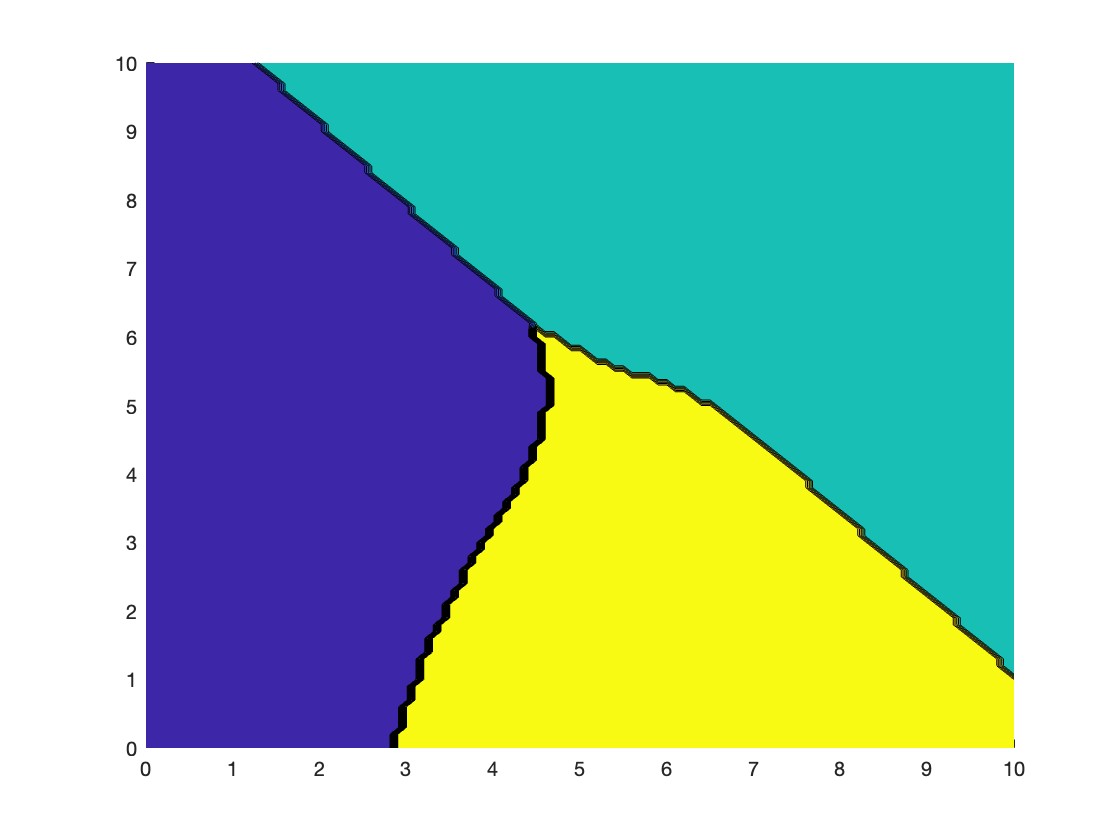

[X1, X2]=meshgrid(x1, x2);
Xtest = [X1(:).'; X2(:).'];
ytest=net1(Xtest);

% back into labels 1-3
ytest_labels=zeros(1,length(ytest));
for i=1:1:length(ytest)
    [~,label] = max(ytest(:, i));
    ytest_labels(1,i)=label;
end

figure; hold on
contourf(x1, x2, reshape(ytest_labels, size(X1)) )
hold off

2b) Regression:

% Create network: specify number of neurons in each layer:
rng(3456);
clear net2
% [e.g., [2 6 2] would create 3 hidden layers with 2,6,2 neurons in each]
net2 = patternnet([3 3]); % 2 hidden layers with 3 neurons each. sure.
disp('net2 = patternnet([3 3]);');

net2 = patternnet([3 3]);



% don't divide data into training, testing, validation.
net2.divideFcn='';

% Train network:
net2 = train(net2,X,y);
disp('net2 = train(net2,X,y);');

net2 = train(net2,X,y);


view(net2);

Contour plot:

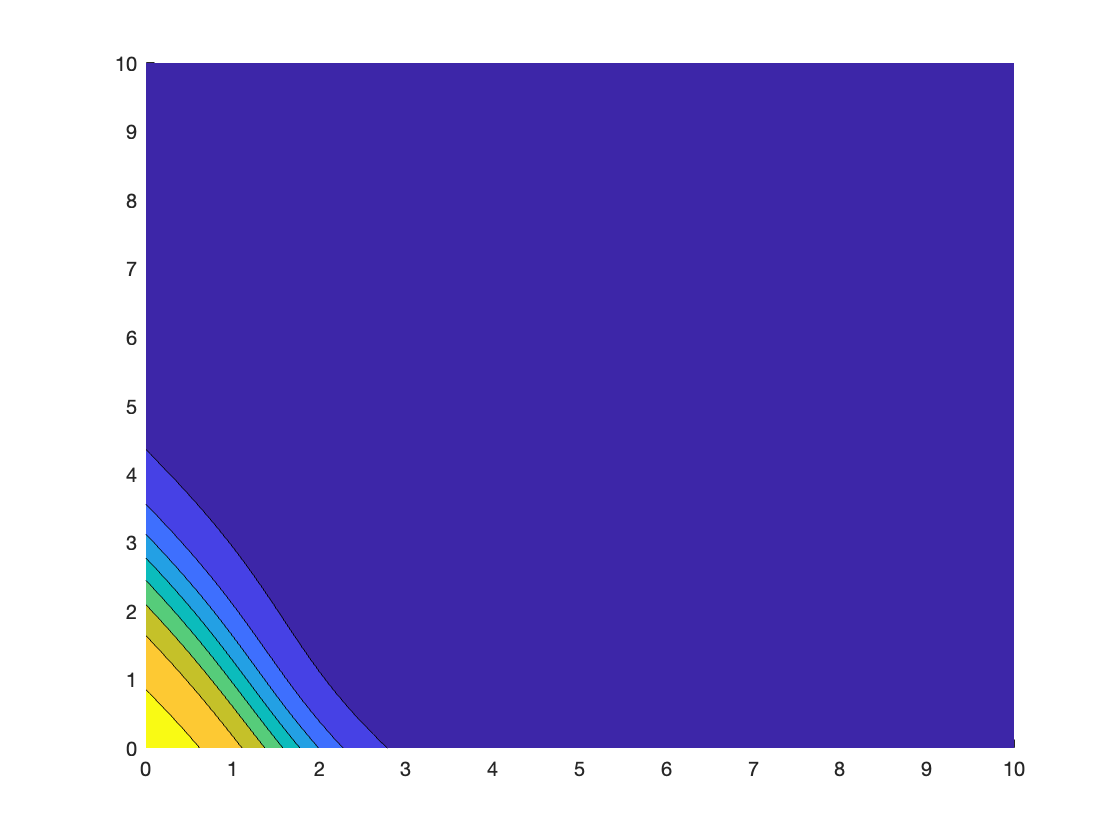

ytest2=net2(Xtest);

figure; hold on
contourf(x1, x2, reshape(ytest2, size(X1)) )
hold off

## 3

clear all
load saved-network-HW-10.mat
% w2, b2, w3, b3, w4, b4

Activation functions:

tansig = @(zl) ( 2./(1+exp(-2.*zl)) ) -1;
linear = @(zl) zl;

Input space:

x1=0:0.1:1;
x2=x1;

To make this easier, combine bs into ws and add 1's to input

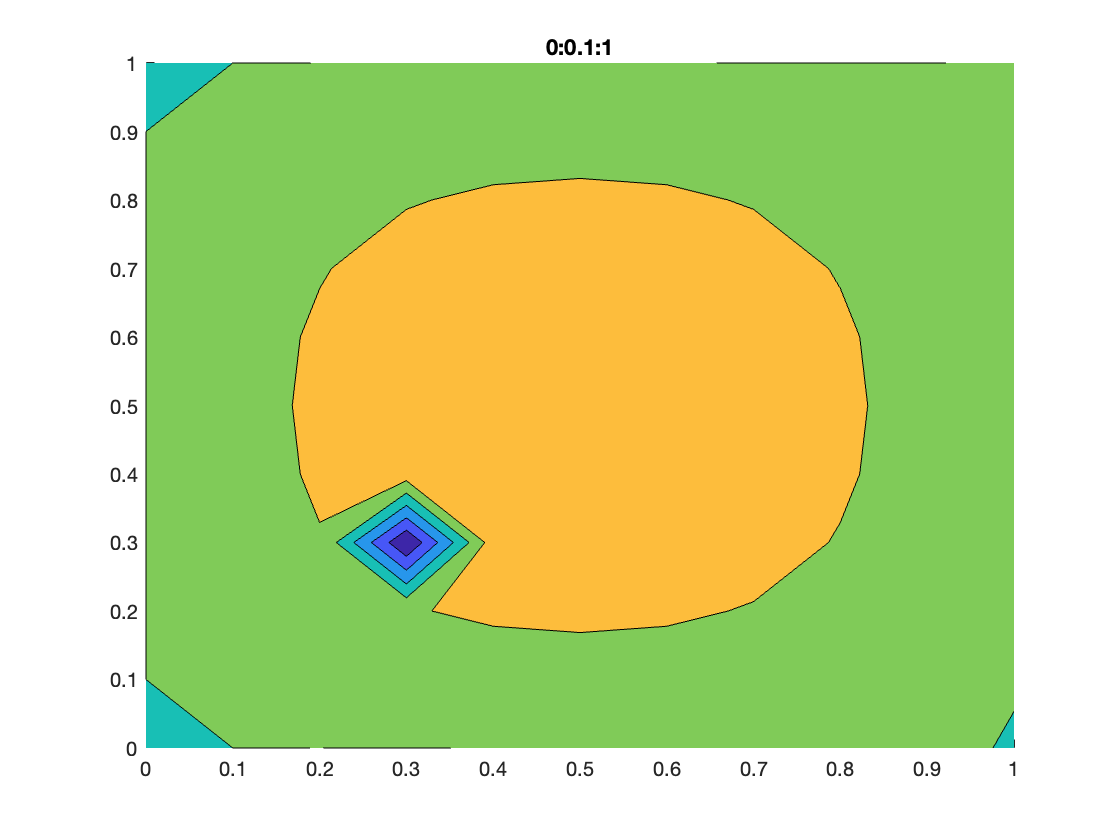

w2 = horzcat(w2, b2);
w3 = horzcat(w3, b3);
w4 = horzcat(w4, b4);

[X1, X2]=meshgrid(x1, x2);
Xtest = [X1(:).'; X2(:).'];
[~, N] = size(Xtest);
Xtest = vertcat(Xtest, ones([1 N]));

% Running network
z2 = w2*Xtest;
a2 = tansig(z2);

[~, N] = size(a2); a2 = vertcat(a2, ones([1 N]));
z3 = w3*a2;
a3 = tansig(z3);

[~, N] = size(a3); a3 = vertcat(a3, ones([1 N]));
z4 = w4*a3;
a4 = linear(z4);

figure; hold on; title('0:0.1:1')
contourf(x1, x2, reshape(a4, size(X1)) )
hold off

Now with a different input space:

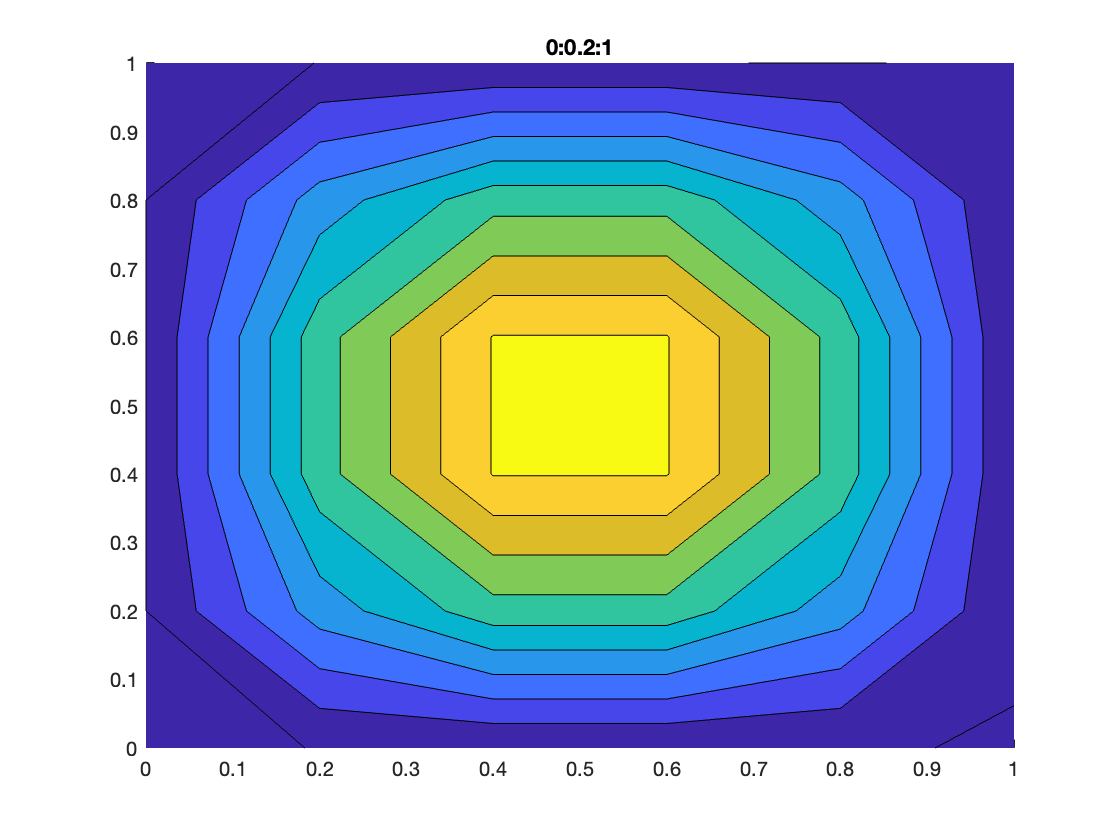

x1=0:0.2:1;
x2=x1;

% add row of 1's instead of dealing with separate b's
[X1, X2]=meshgrid(x1, x2);
Xtest = [X1(:).'; X2(:).'];
[~, N] = size(Xtest);
Xtest = vertcat(Xtest, ones([1 N]));

% Running network
z2 = w2*Xtest;
a2 = tansig(z2);

[~, N] = size(a2); a2 = vertcat(a2, ones([1 N]));
z3 = w3*a2;
a3 = tansig(z3);

[~, N] = size(a3); a3 = vertcat(a3, ones([1 N]));
z4 = w4*a3;
a4 = linear(z4);

figure; hold on; title('0:0.2:1')
contourf(x1, x2, reshape(a4, size(X1)) )
hold off

There is a local 0.1 width spot of lowered output with this network that is missed with just 0.2 input increments. This is likely the result of overfitting due to noise in the training data that has slightly lower values (from noise not true signal) in that region.

The problem may be overcome by training with noisier data, [].